#  Teorema fundamental del cálculo 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Una conexión profunda entre el cálculo diferencial e integral es la relación entre [funciones de acumulación](matlab:open('./Riemann.mlx')) y [funciones derivadas](https://github.com/MathWorks-Teaching-Resources/Calculus-Derivatives). 

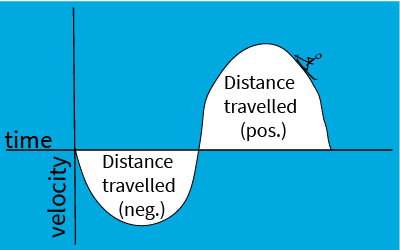

El área geométrica bajo una curva corresponde a la acumulación total del producto de los valores seguidos a lo largo de cada eje. En esta imagen, la velocidad multiplicada por el tiempo es distancia. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB.

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Practique integrales definidas aleatorias 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear MyFun VarChoice                             
syms t r x z C                       % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;                      % Inicializar un recuento de errores
TotDefProbs = 0;                     % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Values initialized for Antiderivative Practice.")
disp("If the integral does not exist, use DNE. If the integral diverges towards" + ...
    " positive or negative infinity, use INF or -INF, as appropriate.") 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotDefProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [MyFun,VarChoice,bds] = GenProbType(VarOpts);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    TotDefProbs = TotDefProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Run this section 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotDefProbs","var")
    warning("You must initialize values before you can generate a problem.")
elseif TotDefProbs == 0
    warning("You must generate a problem before you can solve a problem.")
else
MyAnswer = str2sym("0");     % Solución definida por el usuario, valor predeterminado 0
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotDefProbs, ...
    AdjustCount,MyFun,VarChoice,bds,MyAnswer,ErrorCount,LastFive);
% resubmissionCheck se define en Funciones auxiliares
% resubmissionCheck registra el intento y proporciona comentarios adecuados
end
                          % Run this section 

Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(TotDefProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)

###  Aplicación de práctica 

Puede practicar en la aplicación Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debe configurar el tipo de problema como "Integrales definidas" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[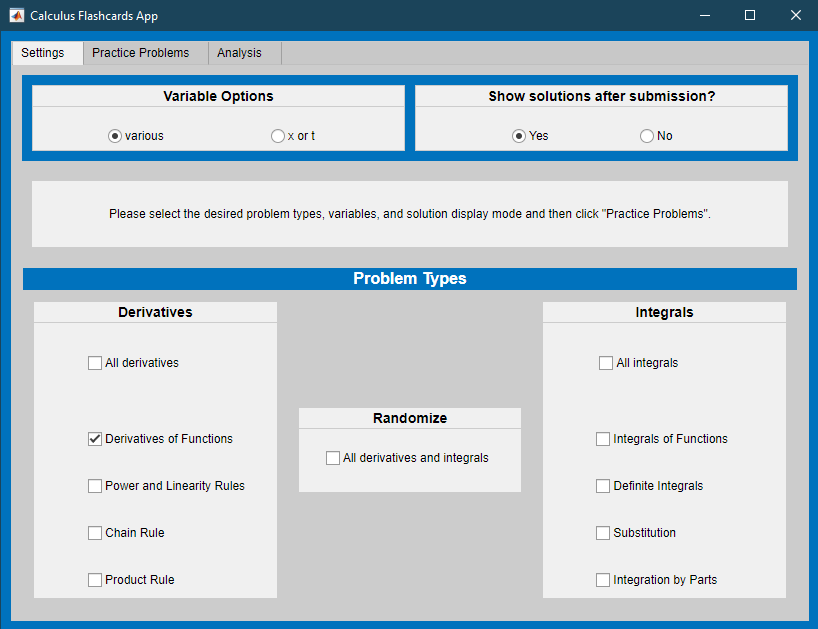](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el icono   en la parte superior derecha del panel Live Editor. 

** Practicar funciones de generación de problemas **

Construir un problema para mostrar 

function [myFun,varChoice,bds] = GenProbType(varOpts)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% [a, b] son ��los límites de la integral definida, si requerido

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
        syms f(x) x 
        [f(x),~] = GenFunDiff([1 10],x,[1 10],0);
        myFun = f(varChoice);
        bds = randi([-3,4],[1 2]);
        a = bds(1); %#ok<NASGU>
        b = bds(2); %#ok<NASGU>
        % Mostrar el problema integral
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice,a,b)")
end 

Generar funciones aleatorias apropiadas 

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end 

Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,bds,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
   [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
    end
else
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
end
end 

Verificar que la solución enviada sea correcta 

function [lastFive,errorCount] = Check1(myFunc,myVar,bds,myAnswer,errorCount,lastFive)
% check1 genera respuestas correctas integrando y actualizando
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
tol = 1e-3;
correctAnswer = int(myFunc,myVar,bds);
if isequal(myAnswer,str2sym("DNE"))
    myAnswer = nan;
end
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isnan(correctAnswer) && isnan(myAnswer)
    disp("That answer is correct. This integral does not exist.")
    lastFive(5) = 1;
elseif isinf(correctAnswer) && isinf(myAnswer)
    if sign(real(correctAnswer))==sign(myAnswer)
        disp("That answer is correct. The integral diverges towards:")
        disp(correctAnswer)
        lastFive(5) = 1;
    else
        disp("You are correct that the integral diverges, but not about the direction.")
        disp("The integral diverges towards: ")
        disp(correctAnswer)
        lastFive(5) = 0;
    end
elseif ~isreal(myAnswer)
    disp("Your answer should be a finite real number. Please try again.")
elseif abs(double(myAnswer-correctAnswer))<tol
    disp("That answer is rounded. A more precise value is:")
    disp(correctAnswer)
    lastFive(5) = 1;
else
    disp("That is incorrect. Remember to be precise. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end 

Analizar los resultados y dar retroalimentación 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end